close all

## Hilbert Huang Transform:

## Fourier and HHT

### FFT is theoretic; but HHT is only empirical (so far) 

To date, HHT is an **empirical** method: it is based on observation and experience.

Fourier is a **theoretical** method.  Based on proven mathematical theroms and laws.

*However,* Consider that HHT originated in 1985.  Fourier originated in 1807 and did not transition from empirical to theoretical until 1933 when the final proofs were completed.

Due to the internet,  improved communications, and widespread interest and application it will likely take less time for HHT to become theoretic.  It only needs more pure mathematicians looking at it.  There are groups and conferences dedicated to theory and application behind HHT.

### FFT is linear

Most real-world data is non-linear.  In order to use FFT analysis, assumptions must be made to linearize the problem.  these a-priori (pre-supposed) assumptions lead to creations of fourier components with mathematical meaning but no physical meaning, or else lead to changes to the data (such as windowing) which are not part of the physical underpinnings of the data.  Quite often, it leads to both.

### FFT is stationary

Most real world data is non-stationary. Over time, it is changing in condition (for example in frequency and amplitude).  FFT is a stationary transform.  a priori assumptions of stationarity require us to ignore the nonstationarity and determine only stationary approximations.  A non-stationary method was urgently needed in many fields and this is one of the primary drivers behind the work of Huang et al.

## The HHT process

1) Use Emprical Mode Decomposition (EMD) to determine a finite number of  Intrinsic Mode Functions (IMF)

2) For each IMF, perform a Hilbert Transform to deirve the analytic signal.  The analystic signal can then be analysed point-by-point for its amplitude and phase.

### Empirical mode decomposition

Based on the assumption that any data set consists of a sum of intrinsic modes of oscillations.  Fourier transform is based on a specific case of this assumption where each of the IMFs are linear and stationary (i.e. a single frequency and amplitude).  EMD IMFs may also be non-linear and non-stationary.

Each interinsic mode of oscillation will have an equal number of extrema and zero crossings. and the oscillations are symmetric with respect to the local mean.  Later we will discuss why these two requirments are actually too rigorous a requirement for IMFs that represent actual physical phenomina, so the requirment in HHT is relaxed to the same number of extrema and crossings plus or minus 1. and the oscilaltions do not need to be strictly symetric.  (IMF optimization is exetnsively studied and one of the reasons that HHT remains empirical. You will need to look at the details to determine if your IMFs are appropriate for a good result representing physical phenomina)  

#### Steps of EMD

The EMD is performed in two nested loops.  The outer loop yeilds one Intrinsic Mode Function (IMF).  The inner loop "sifts" the signal, minus the previous IMF if there is one:

- Find the local extrema of the (remaining) signal to be decomposed.

- Interpolate the cubic spline (somtimes b-spline) between the extrema.

- Find the mean of the  upper and lower extrema.

- Subtract the mean from the signal, this is the residual.

-  Check for the sifting stopping criteria:  a) Cauchy type convergence test ( normalized squared difference between two sifting operations is "sufficiently small") or b) The sifting process has been performed S consecutive times.

- If neither stop criteria is met, subtract the IMF from the remaining signal and repeat the sifting process.

This inner, sifting loop is repeated and one IMF is created per sifting operation until either:

- The ratio of the original signal energy (10 x log Euclidian norm (the root of thesum of the squared ampitudes)) to the energy of the residual is a significantly large number.  In other words, there is not much energy left in the residual.

- The remainder becomes monotonic and no more IMFs can be found.  In this case the remainder is a trend line.

##  Example:

### Gaussian modulated quadratic chirp

fs = 2000;
t = 0:1/fs:2-1/fs;
q = ex1(t);

Use EMD to visualize the intrinsic mode functions

ans = 'IMF 0'

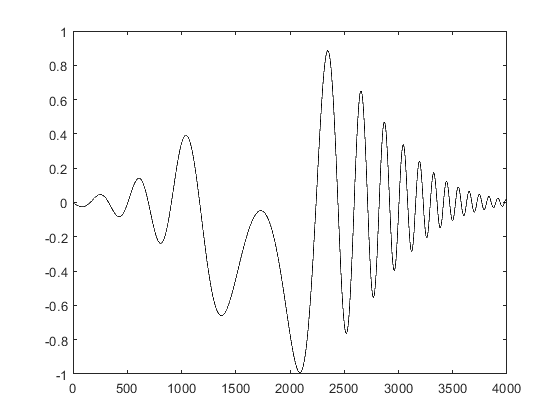

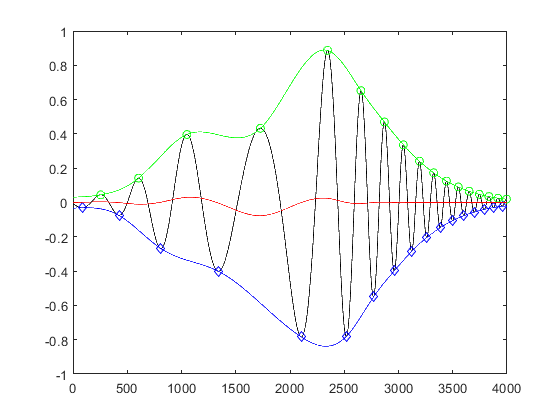

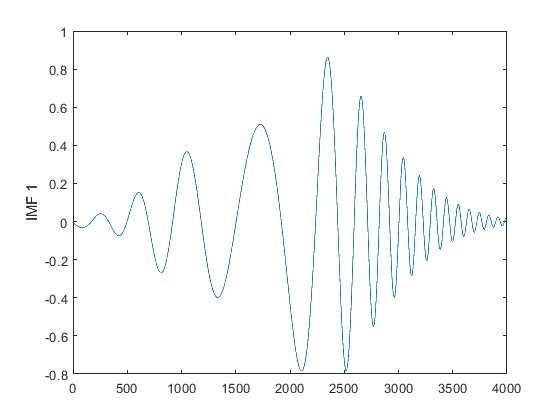

ans = 'IMF 1'

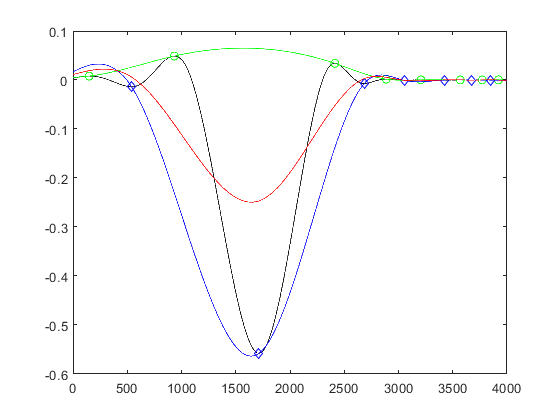

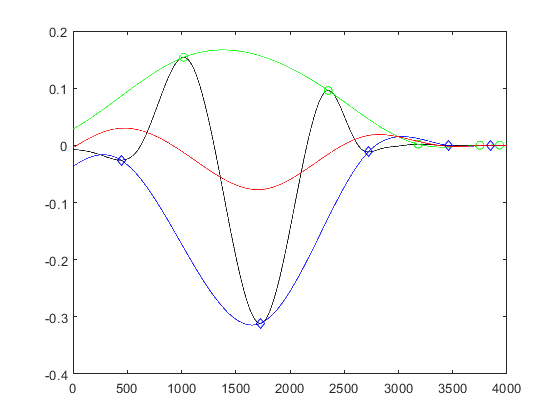

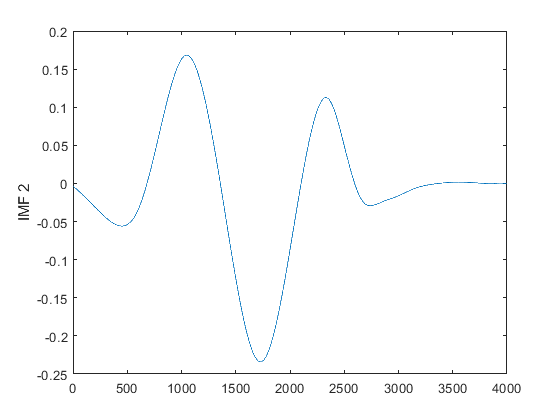

ans = 'IMF 2'

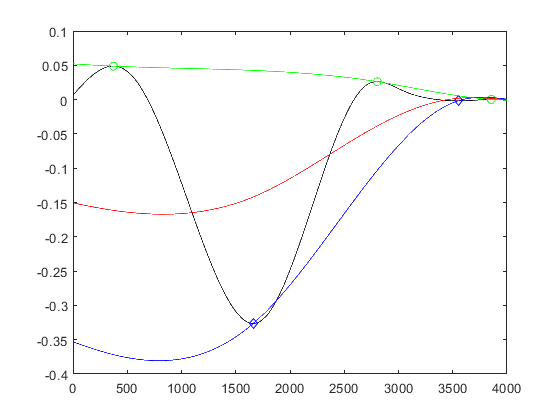

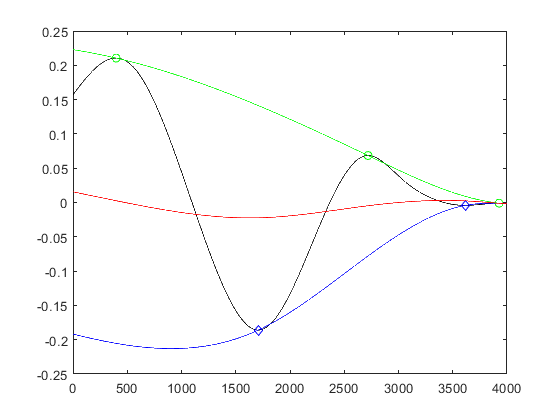

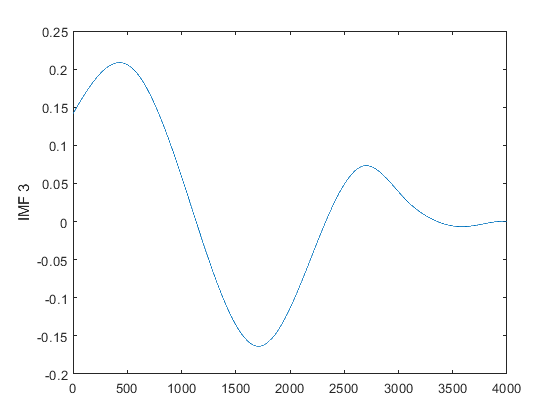

ans = 'IMF 3'

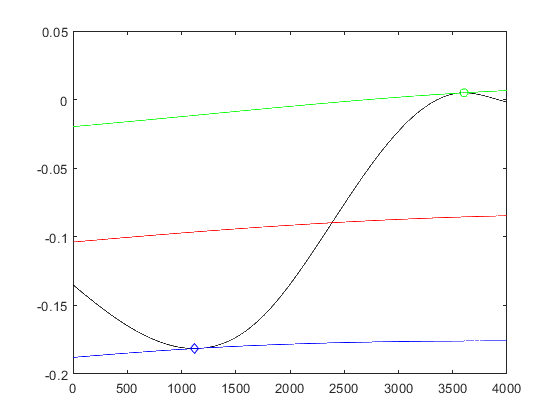

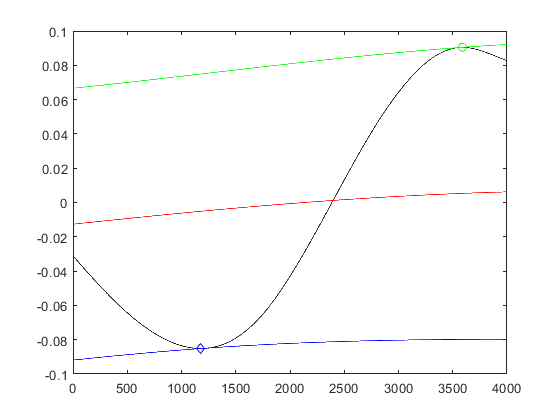

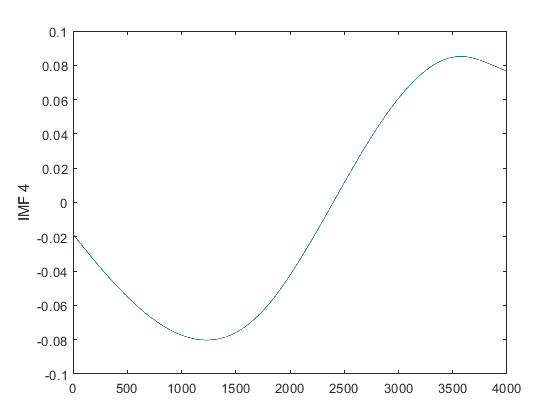

ans = 'IMF 4'

[IMFs,resid] = myEmd(q);

Plot the IMFs:

nIMFs = size(IMFs,2);
figure()
subplot(nIMFs+2,1,1)
plot(q)
ylabel('original')
for i = 1:nIMFs
    subplot(nIMFs+2,1,i+1)
    plot(IMFs(:,i))
    ylabel(sprintf('IMF %d',i))
end
subplot(nIMFs+2,1,6)
plot(resid)
ylabel('residual')

## Analyse the spectrum of the IMFs

This is where the hilbert transform comes into play.  The hilbert transform creates an "analytic signal (in the complex domain) in quadrature with the original signal.  Using this signal, one can determine the amplitude and phases of the signal at every point.  The derivative of the phase at any point is the instantanious frequency.

While the Hilbert function uses Fourier and inverse Fourier to create the analtic signal, this does not suffer from the same assumptions of stationarity and linearity as mentioned above.  Fourier transform completely describes a time domain signal in terms of frequencies, even if those frequencies represent only mathematical and not physical underpinnings.  To create the analytic signal, an inverse fourier transform is performed which recovers the original signal and it's analytic counterpart.

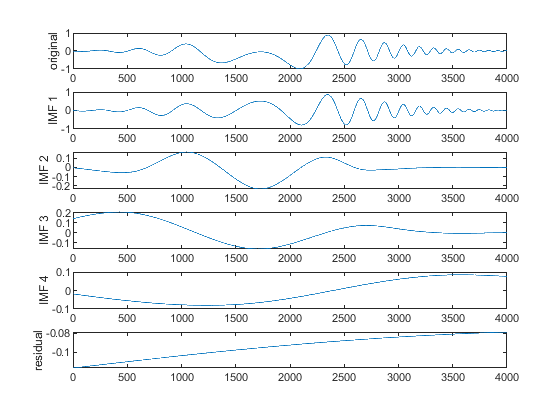

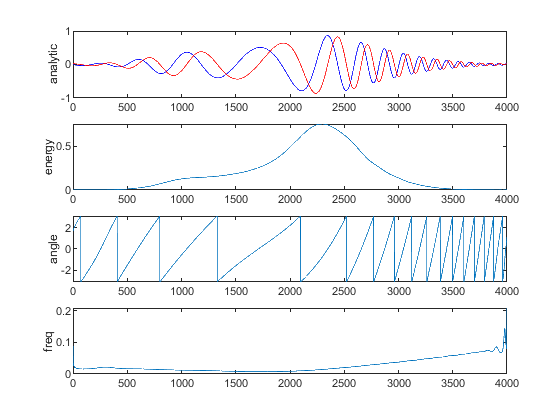

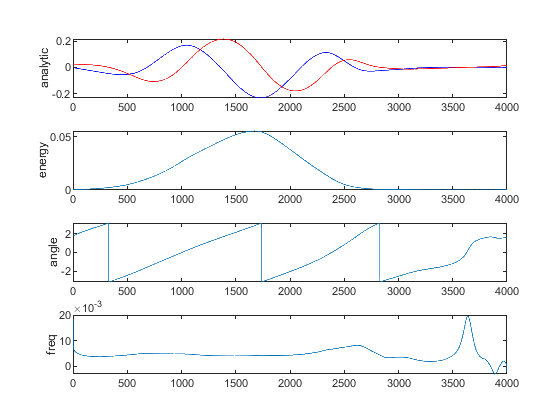

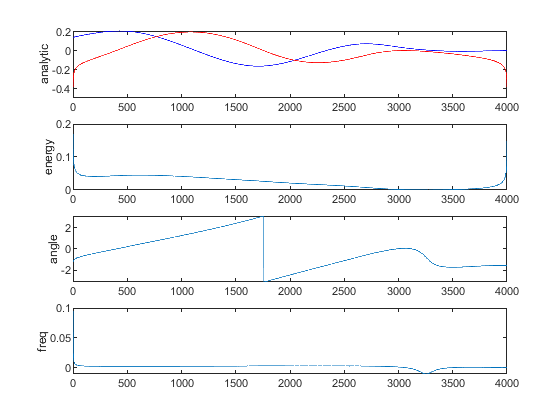

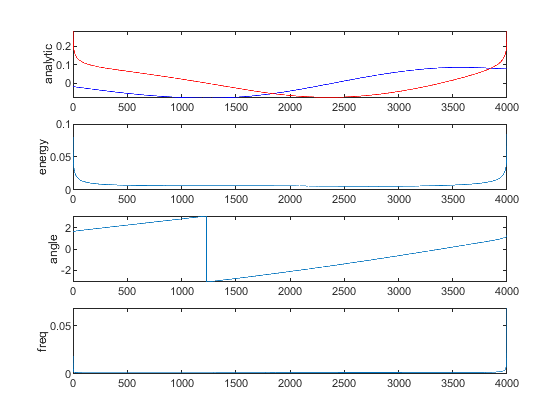

myHht(IMFs)

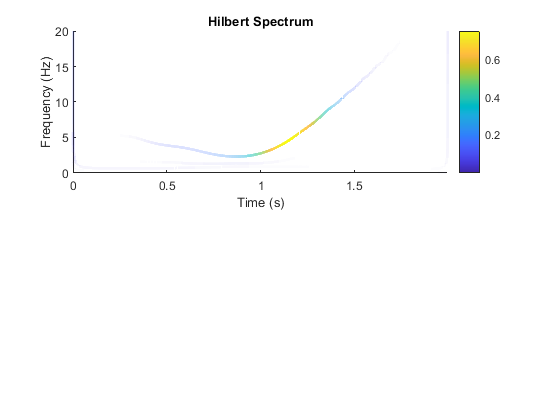

figure()
subplot(2,1,1)
hht(IMFs,fs,'FrequencyLimits',[0 20]);

subplot(2,1,2)
plot(q)

## Considerations:

## EMD Stopping Criteria:

#### Criteria A: Cauchy type convergence:

$\sum^\inf_{i=0}ai$ is convergent if and only if for every $\epsilon$there is a natural number *N* such that: 

$|a_{n+1}+a_{n+2}+...+a_{n+p}|<\epsilon$ (in other words, the series converges towards constant number)

Usually, we check to see if the change in values is small, meaning it is approaching the convergence.The question for any cauchy convergence test is what is the tolarance of that number.  In other words, how close to the number does one need to get?

One problem with the cauchy test for EMD, is the squared difference may be small, but that does not guarantee that the proto IMF meets the defiition of an IMF:  That it have the same numbers of zero-crossings and extrema (give or take one).

I will not go into the various methods of determining the tolarance and checking that an IMF meets the definition but instead will refer you to the textbook *Hilbert Huang Transform and its Applications, 2nd edition, *2014, by Huang and Shen.

#### Criteria B: Number of sifting iterations (S)

To overcome the issue with convergence not meeting the definition of an IMF, Huang, the sift does not necessarily need to converge if it has the same number of extrema and zero crossing (give or take one) for some number of sifting iterations that they called *S*.  

The questin here is what number S is appropriate.  The selection is ad-hoc and needs justification.  In 2003, Huang et-al developed the Ensemble Empirical Mode Decomposition (EEMD) to address the issues of ending the sifting when convergence does not meet a tolarance.  The ensemble provides a mean and confidence limit by using different numbers for S and injecting different random noise sets to the original signal.  This technique needs to be used when the original signal is noisy and the EMD is not able to converge.

### Extrema interpolation

Which interpolation method is best to use?  Huang et. al determined that cuic was best.  and many others have been tried.  B-spline has been found to be more effective in some types of problems.  Chapter 4 of the text book covers b-spline.

Another issue to be considered dutring interpolation are the initial conditions

### Hilbert Transform considerations

#### Fourier assumptions

Hilbert transform can be performed using Fourier transform followed by inverse Fourier transform.  The assumptions that are problematic in using Fourier for spectral analysis are not an issue here since inverse Fourier returns the original signal.  

#### End Effects

As seen in the HHT examples above, there are isues with the "end effects".  These are due to discontinuities at the ends which , to fourier, look like very high frequency signal components  these are, of course, aliased into the original and cause distortions.

There is much in the literature on mitigating end effects.  Extrapolating the original signal being one of them (also called signal extension).  In many cases, it is very difficult to extrapolate the original signal but serial methods are available:

- Characteristic Wave Extending

- Mirror Extending

- Data Extending

- Similarity Searching

Windowing the data is a distortion and may not be appropriate for HHT because it will change or hide the actual physical underpinnings that we are trying to analyse.  Also just deling with the original data does not assure that the data input to each iteration of the sifting process will not have discontinuities.  One issue is that end effects tend to accumulate as each IMF is determined.

#### Bedrosian theorem (1963)

The Hilbert transform (HT) of the product of a low-pass and a high-pass signal with non-overlapping spectra is the product of the HT of the low-pass and the HT.  The issue is that many real-world signals are overlapping (or non-disjoint).  To circumvent this difficulty Huang (2005) and Huang et. al (2006) proposed a normalization scheme which empirically separates an IMF into AM and FM parts uniquely.  This is covered in chapter 1.3.1 of the textbook.

## Conclusion

The HHT is a (relatively) new empirical method for analysing non-linear and/or non-stationary data that makes up for the majority of data in the real world.  It overcomes the a-priori assumtions of Fourier transform which is a good mathematical representation of a time domain signal in the frequency domain but does not well represent the physical underpinnings of the data (this is true of linear and stationary data as well).

There is a huge amount of interest and application in many many fields, including power and energy.

Today it is empirical, but ther interest is so high that mathematicians are working to make it theoretic.  Recall that it took Fourer transform almost 130 years to go from empirical to theoretic.  HHT will probably become theoretic much more quickly.

There are many considerations, so (as in Fourier) it is important to *"look at your fish" (search (Samuel H Scudder).  *As with Fourier, it is important to actually understand what is happening in the math and why it is happening.  Anyone who does not, gets what they deserve.

## Discussion

Example 3rd order ODE:


$$x'' + x(1+\epsilon x^2) = \gamma cos(\omega t)$$


function dxdt = f(t,x,g,e,w)
    dxdt = [x(2);
            (g.*cos(w.*t)-x(1).*(1+(e.*x(1).^2))) ];   
end

function x = ex1(t)
    x = chirp(t-2,4,1/2,6,'quadratic',100,'convex').*exp(-4*(t-1).^2);
end